# Poisson equation in 2D

## 1. Case description

We want to numerically solve the **Poisson equation on a 2D rectangular domain** using the Successive Over-Relaxation method:


$$\frac{\partial^2 f}{\partial x^2 }+\frac{\partial^2 f}{\partial y^2 }=S\left(x,y\right)$$
 

Using the standard **finite differences** to discretize, we have:


$$\frac{f_{i+1,j} -2f_{i,j} +f_{i-1,j} }{h_x^2 }+\frac{f_{i,j+1} -2f_{i,j} +f_{i,j-1} }{h_y^2 }=S_{i,j}$$


Solving for $f_{i,j}$, we have:


$$f_{i,j} =\frac{1}{2\left(h_x^2 +h_y^2 \right)}\left\lbrack h_y^2 \left(f_{i+1,j} +f_{i-1,j} \right)+h_x^2 \left(f_{i,j+1} +f_{i,j-1} \right)-h_x^2 h_y^2 \;S_{i,j} \right\rbrack$$


In particular, in case of same grid step along the two directions (i.e. $h_x =h_y =h$), the equation above becomes:


$$f_{i,j} =\frac{1}{4}\left\lbrack f_{i+1,j} +f_{i-1,j} +f_{i,j+1} +f_{i,j-1} -h^2 {\;S}_{i,j} \right\rbrack$$


### a. The Jacobi method

According to the Jacobi method, we solve for $f_{i,j}$  and use the right hand side to compute a new value. If we denote the old values by $\alpha$ and the new ones with $\alpha +1$, we have:


$$f_{i,j}^{\alpha +1} =\frac{1}{2\left(h_x^2 +h_y^2 \right)}\left\lbrack h_y^2 \left(f_{i+1,j}^{\alpha } +f_{i-1,j}^{\alpha } \right)+h_x^2 \left(f_{i,j+1}^{\alpha } +f_{i,j-1}^{\alpha } \right)-h_x^2 h_y^2 {\;S}_{i,j}^{\alpha } \right\rbrack$$


The Jacobi method is very simple, but many iterations are required to reach an accurate solution.The iteration must be carried out until the solution is sufficiently accurate. To measure the error, define the **residual**:


$$R_{i,j}^{\alpha } =\frac{f_{i+1,j}^{\alpha } -2f_{i,j}^{\alpha } +f_{i-1,j}^{\alpha } }{h_x^2 }+\frac{f_{i,j+1}^{\alpha } -2f_{i,j}^{\alpha } +f_{i,j-1}^{\alpha } }{h_y^2 }-{\;S}_{i,j}^{\alpha }$$


At steady-state the residual should be zero. The pointwise residual or the average absolute residual can be used, depending on the problem. Often, simpler criteria, such as the change from one iteration to the next, are used.

### b. The Gauss-Siedler method

Although the Jacobi iteration is a very robust iteration technique, it converges **very ****slowly**.We therefore seek a way to **accelerate** the convergence to steady-state, making use of the fact that it is only the steady-state that is of interest. Here we introduce the **Gauss-****Seidler **method.

In the Gauss-Siedler method, the Jacobi iteration is improved by using new values as soon as they become available:


$$f_{i,j}^{\alpha +1} =\frac{1}{2\left(h_x^2 +h_y^2 \right)}\left\lbrack h_y^2 \left(f_{i+1,j}^{\alpha } +f_{i-1,j}^{\alpha +1} \right)+h_x^2 \left(f_{i,j+1}^{\alpha } +f_{i,j-1}^{\alpha +1} \right)-h_x^2 h_y^2 {\;S}_{i,j}^{\alpha } \right\rbrack$$


From a programming point of view, Gauss-Seidleriteration is even simpler than Jacobi iteration since only one vector with f values is needed.

### c. The Successive Over-Relaxation (SOR) method

The Gauss-Seidler iteration can be accelerated even further by various acceleration techniques. The simplest one is the Successive Over-Relaxation (SOR) iteration:


$$f_{i,j}^{\alpha +1} =\frac{1}{2\left(h_x^2 +h_y^2 \right)}\left\lbrack h_y^2 \left(f_{i+1,j}^{\alpha } +f_{i-1,j}^{\alpha +1} \right)+h_x^2 \left(f_{i,j+1}^{\alpha } +f_{i,j-1}^{\alpha +1} \right)-h_x^2 h_y^2 {\;S}_{i,j}^{\alpha } \right\rbrack \beta +f_{i,j}^{\alpha +1} \left(1-\beta \right)$$


The SOR iteration is very simple to program, just as the Gauss-Seidler iteration. The user must select the coefficient. It must be bounded by $1<\beta <2$. $\beta =1\ldotp 5$ is usually a good starting value.

## 2. Implementation

### a. Numerical setup

We start defining the relevant data, i.e. the lengths of the sides and the number of grid points along the two directions, the maximum number of iterations, and the over-relaxation coefficient:

lengthx=2.0;            % domain length along x [m]
lengthy=2.0;            % domain length along y [m]
nx=39;                  % number of grid points along x
ny=39;                  % number of grid points along y
max_iterations=5000;    % max number of iterations
beta=1.;                % SOR coefficient (1 means Gauss-Siedler)

We pre-process the input data (calculation of grid steps, memory allocation, etc.):

% Grid step calculation
hx=lengthx/(nx-1);      % grid step along x [m]
hy=lengthy/(ny-1);      % grid step along y [m]

% Memory allocation
f=zeros(nx,ny);         % current solution
S=zeros(nx,ny);         % source term

We can now provide the boundary conditions. In this specifc example, we are considering the following Dirichlet condition along the west side ($x=0$), where $f_{\textrm{inlet}}$ is a constant value (for example $f_{\textrm{inlet}} =1$):


$$f\left(x=0;y\in \left\lbrack \frac{L_y }{3};\frac{{2L}_y }{3}\right\rbrack \right)=f_{\textrm{inlet}}$$



$$f\left(x=0;y\in \left\lbrack 0;\frac{L_y }{3}\right\rbrack \cup \left\lbrack \frac{{2L}_y }{3};L_y \right\rbrack \right)=0$$


The boundary condition above can be coded as:

% Boundary conditions (west side)
f(1, ny*1/3:ny*2/3) = 1;

Along the remaining sides, we simply fix the following Dirichlet boundary conditions:


$$f=0$$


There is no need to explicitly fix the boundary conditions, because we simply ask for $f=0$, which is automatically satisfied since we allocated and initialized $f$ above.

The figure below better clarifies the boundary conditions we are implementing.

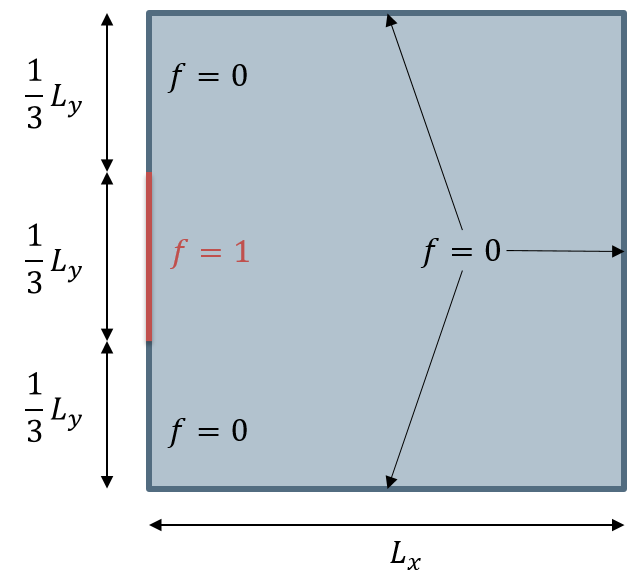

### b. Iteration loop

We can now proceed with the numerical solution, by applying the SOR method. At each iteration, we have:


$$f_{i,j}^{\alpha +1} =\frac{1}{2\left(h_x^2 +h_y^2 \right)}\left\lbrack h_y^2 \left(f_{i+1,j}^{\alpha } +f_{i-1,j}^{\alpha +1} \right)+h_x^2 \left(f_{i,j+1}^{\alpha } +f_{i,j-1}^{\alpha +1} \right)-h_x^2 h_y^2 {\;S}_{i,j}^{\alpha } \right\rbrack \beta +f_{i,j}^{\alpha +1} \left(1-\beta \right)$$


The corresponding code is reported in the following (notice that only internal points are updated):

In order to check the convergence, we calculate the current residual:

If the residual is below a user-defined threshold, we can stop the iterations.

### c. Graphical output

At the end of iterations, we can plot the solution. For example:

## 3. Bringing it All Together

Let's bring it all together.

% Cleaning the MATLAB environment
%-------------------------------------------------------------------------%
close all;
clear variables;

% User-defined data
%-------------------------------------------------------------------------%
lengthx=2.0;            % domain length along x [m]
lengthy=2.0;            % domain length along y [m]
nx=39;                  % number of grid points along x
ny=39;                  % number of grid points along y
max_iterations=5000;    % max number of iterations
beta=1.;                % SOR coefficient (1 means Gauss-Siedler)

% Pre-processing of user-defined data
%-------------------------------------------------------------------------%
% Grid step calculation
hx=lengthx/(nx-1);      % grid step along x [m]
hy=lengthy/(ny-1);      % grid step along y [m]

% Memory allocation
f=zeros(nx,ny);         % current solution
S=zeros(nx,ny);         % source term

% Boundary conditions (west side)
f(1, ny*1/3:ny*2/3) = 1;

% Iterations
%-------------------------------------------------------------------------%
for l=1:max_iterations
    
    for i=2:nx-1
        for j=2:ny-1
            f(i,j)= beta/(2*(hx^2+hy^2))*...
                    (   (f(i+1,j)+f(i-1,j))*hy^2 ...
                      + (f(i,j+1)+f(i,j-1))*hx^2 ...
                      - hx^2*hy^2*S(i,j) ...
                    ) + ...
                    (1.0-beta)*f(i,j);
        end
    end
    
    % Residual
    res=0;
    for i=2:nx-1
        for j=2:ny-1
            res=res+abs( (f(i+1,j)-2*f(i,j)+f(i-1,j))/hx^2 + ...
                         (f(i,j+1)-2*f(i,j)+f(i,j-1))/hy^2 - S(i,j) );
        end
    end
    
    tot_res = res/((nx-2)*(ny-2));
    fprintf('Iteration: %d - Residual: %e\n', l, tot_res);
    
    if (tot_res < 0.001)
        break;
    end
end

Iteration: 1 - Residual: 2.461164e+00
Iteration: 2 - Residual: 1.914237e+00
Iteration: 3 - Residual: 1.610386e+00
Iteration: 4 - Residual: 1.414566e+00
Iteration: 5 - Residual: 1.275758e+00
Iteration: 6 - Residual: 1.170954e+00
Iteration: 7 - Residual: 1.088259e+00
Iteration: 8 - Residual: 1.020866e+00
Iteration: 9 - Residual: 9.645737e-01
Iteration: 10 - Residual: 9.166316e-01
Iteration: 11 - Residual: 8.751551e-01
Iteration: 12 - Residual: 8.388039e-01
Iteration: 13 - Residual: 8.065950e-01
Iteration: 14 - Residual: 7.777884e-01
Iteration: 15 - Residual: 7.518150e-01
Iteration: 16 - Residual: 7.282289e-01
Iteration: 17 - Residual: 7.066755e-01
Iteration: 18 - Residual: 6.868689e-01
Iteration: 19 - Residual: 6.685755e-01
Iteration: 20 - Residual: 6.516031e-01
Iteration: 21 - Residual: 6.357916e-01
Iteration: 22 - Residual: 6.210065e-01
Iteration: 23 - Residual: 6.071341e-01
Iteration: 24 - Residual: 5.940777e-01
Iteration: 25 - Residual: 5.817541e-01
Iteration: 26 - Residual: 5.700917

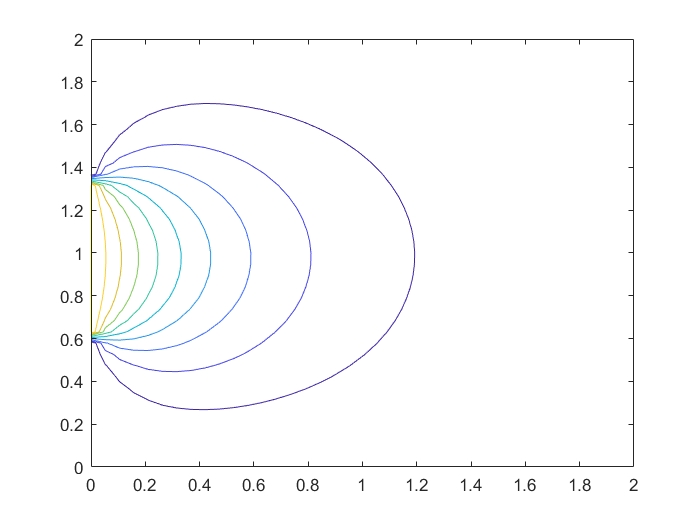

% Graphical output
%-------------------------------------------------------------------------%
xaxis = 0:hx:lengthx;
yaxis = 0:hy:lengthy;
contour(xaxis, yaxis, f');

## 4. Exercises

- Identify the optimal value of $\beta$, i.e. the value which minimizes the number of iterations.

- Demonstrates that the method numerical discretization adopted is 2nd order accurate in space.

- What happens if the inlet value is time depending according to the following expression: 

- Solve a new case, in which the boundary conditions are $f=0$ everywhere (on the west side too) and the source term has the following expression:


$$S\left(x,y\right)={\left(x-1\right)}^2 +{\left(y-1\right)}^2$$
